# Máster en Ing. Matemática y Computación

#### `Autor: Dr. Abdelmalik Moujahid`

# Mapas Discretos

# Puntos fijos y estabilidad

- **Un mapa** es una función $f:\Re^n \to \Re^n$. Dada dicha función y un punto $x\in \Re^n$, se define la **órbita** de $x$ como la **secuencia**:

#### 
$$\left(x,\;f\left(x\right),f\left(f\left(x\right)\right),\ldotp \ldotp \ldotp ,f^n \left(x\right),\ldotp \ldotp \ldotp \;\right)$$


            donde $f^n \left(x\right)=f\left(f^{n-1} \left(x\right)\right)$ es la iteración de orden $n$ del mapa $f$.

- La órbita de un punto es equivalente a la trayectoria de un punto en el caso de ecuaciones diferenciales. 

- La analogía entre **mapas** (**ecuaciones en diferencias**) y **flujos** (**ecuaciones diferenciales**) se aprecia mejor si escribimos un mapa como:

#### 
$$x_{n+1} =f\left(x_n \right)$$
  

- La solución de este mapa se obtiene vía iteración: partiendo de un valor inicial $x_0$, generamos una secuencia de valores $x_1 ,x_2 ,x_3 ,\ldotp \ldotp \ldotp ,x_n$. 

- Iterando un mapa es equivalente a integrar una ecuación diferencial.

- Se dice que $x_*$ es un **punto fijo del mapa**  si $x_* =f\left(x_* \right)$. 

- **La estabilidad de un punto fijo** se puede obtener mediante perturbación, es decir, consideramos una pequeña perturbación del punto fijo y analizamos su evolución. 

- Formalmente, sea $x_n =x_* +\epsilon_n$, entonces $x_{n+1} =x_* +\epsilon_{n+1}$.

- Usando una aproximación lineal, tenemos:

#### 
$$\begin{array}{l}
x_* +\epsilon_{n+1} =f\left(x_* +\epsilon_n \right)=f\left(x_* \right)+\epsilon_{n\;} f^{\prime } \left(x_* \right)+\ldotp \ldotp \ldotp \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=x_* +\epsilon_{n\;} f^{\prime } \left(x_* \right)+\ldotp \ldotp \ldotp 
\end{array}$$


            Eliminando $x_*$, obtenemos:


$${\epsilon_{n+1} \;=\epsilon_n }_{\;} f^{\prime } \left(x_* \right)$$


**Concluimos que el punto fijo es stable si **$|f^{\prime } \left(x_* \right)|<1$**, e inestable si **$|f^{\prime } \left(x_* \right)|>1$

# Ejemplo: El Mapa Logístico

## Puntos Fijos

Dado el siguiente mapa unidimensional:


$$x_{n+1} =f\left(x_n \right)=\mu \;x_n \left(1-x_n \right)$$


Para encontrar los puntos de equilibrio del mapa, $x^*$, primero igualamos $x_{n+1}$ a $x_n$:


$$\mu \;x^* \left(1-x^* \right)=x^* \;$$


Resolviendo esta ecuación, obtenemos:

${x_1 }^* =0$  y  ${x_2 }^* =\frac{\;\mu -1}{\mu \;}$

## Estabilidad

Para determinar la estabilidad de estos puntos fijos, necesitamos evaluar la derivada del mapa discreto en cada punto fijo. La derivada del mapa es: $f^{\prime } \left(x_n \right)=\mu \;-2\mu \;x_n$

- Para $x_1 =0$, $f^{\prime } \left(x_1 \right)=\mu \;$. Como el valor absoluto de $f^{\prime }$ es mayor que 1, **el punto fijo es inestable**.

- Para $x_2 =\frac{\;\mu -1}{\mu \;}$, $f^{\prime } \left(x_2 \right)=2-\mu \;$. En este caso, la estabilidad del punto fijo depende del valor de $\mu$. 

- Para $1<\mu <3$, el punto fijo es estable.

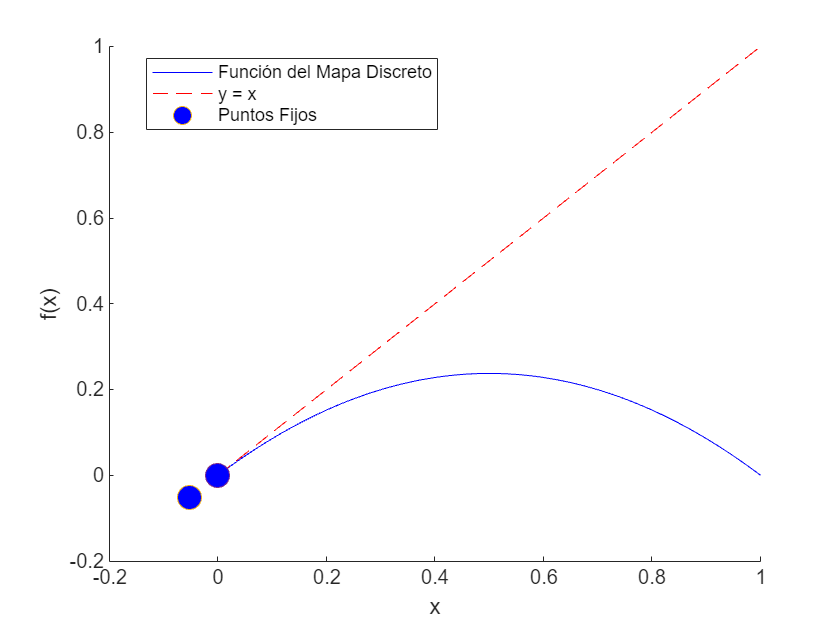

clear all
close all

% Definición de parámetros
mu = .95; % Parámetro de crecimiento de la población

xstar = (mu-1)/mu;

f = @(x) mu * x.*(1 - x);

% Definir el rango de valores para x y el número de iteraciones
x_range = linspace(0, 1, 1000);

num_iterations = 200;

% Visualizar el diagrama de telaraña
figure;
hold on;
% Dibujar la función del mapa discreto
plot(x_range, f(x_range), 'b');
xlabel('x');
ylabel('f(x)');
% Plotear la línea diagonal y=x
plot(x_range, x_range, 'r--');
plot(xstar,f(xstar),'o','MarkerSize',12,'MarkerFaceColor','b')
plot(0,f(0),'o','MarkerSize',12,'MarkerFaceColor','b')

legend('Función del Mapa Discreto', 'y = x', 'Puntos Fijos','Location', 'southwest');

legend("Position", [0.1756,0.79563,0.34583,0.1119])

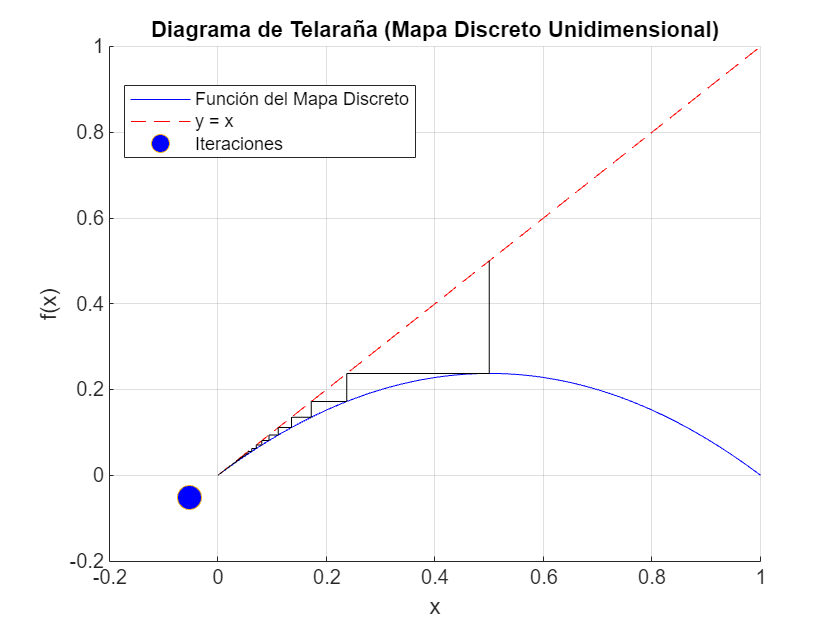



% Visualizar el diagrama de telaraña
figure;
hold on;
% Dibujar la función del mapa discreto
plot(x_range, f(x_range), 'b');
% Plotear la línea diagonal y=x
plot(x_range, x_range, 'r--');
plot(xstar,f(xstar),'o','MarkerSize',12,'MarkerFaceColor','b')



% Realizar las iteraciones del mapa discreto
x_init = .5; % Punto inicial arbitrario

xlabel('x');
ylabel('f(x)');
title('Diagrama de Telaraña (Mapa Discreto Unidimensional)');

grid on;



for i = 1:num_iterations
    x_next = f(x_init);
    % Trazar la línea que conecta los puntos (x, f(x)) y (f(x), f(x))
    plot([x_init, x_init], [x_init, x_next], 'k');
    plot([x_init, x_next], [x_next, x_next], 'k');
    x_init = x_next;
    drawnow;
end
legend('Función del Mapa Discreto', 'y = x', 'Iteraciones','Location', 'southwest');
legend("Position", [0.15133,0.74997,0.34107,0.11476])

# Ejemplo 2:

## Puntos Fijos

Dado el siguiente mapa unidimensional:


$$x_{n+1} =f\left(x_n \right)=\mu -x_n^2$$


Para encontrar los puntos de equilibrio del mapa, $x^*$, primero igualamos $x_{n+1}$ a $x_n$:


$$\mu -x^{*^2 } =x^* \;$$


Resolviendo esta ecuación de segundo orden, obtenemos:


$$x^* =-\frac{1\pm \sqrt{\;1+4\mu \;\;}}{2}$$


Para $\mu =0\ldotp 75$, los puntos fijos son: $\left(-\frac{3}{2},\frac{1}{2}\right)$.

## Estabilidad

Para determinar la estabilidad de estos puntos fijos, necesitamos evaluar la derivada del mapa discreto en cada punto fijo. La derivada del mapa es: $f^{\prime } \left(x_n \right)=-2x_n$

- Para $x_1 =-\frac{3}{2}$, $f^{\prime } \left(x_1 \right)=3$. Como el valor de $f^{\prime }$ es mayor que 1, **el punto fijo es inestable**.

- Para $x_2 =\frac{1}{2}$, $f^{\prime } \left(x_2 \right)=1$. Como el valor de $f^{\prime }$ es igual que 1, no es posible determinar la estabilidad del punto fijo utilizando únicamente la derivada.

## Puntos Fijos y su Estabilidad

clear all

syms x

mu_value = 0.75;

% Derivar el mapa discreto con respecto a x
df_dx = diff(mu_value - x^2, x);

% Encontrar los puntos fijos del mapa en función de mu
puntos_fijos = solve(mu_value - x^2 - x, x);

Conversion to logical from sym is not possible.

Error in sym/solve (line 299)
if sol == eng.evalin2sym('FAIL')


% Mostrar los puntos fijos en función de mu
disp('Puntos fijos del mapa en función de mu:');
disp(puntos_fijos)
% Evaluar las derivadas en los puntos fijos
stability = zeros(size(puntos_fijos));
for i = 1:length(puntos_fijos)
    stability(i) = subs(df_dx, x, puntos_fijos(i));
end

% Mostrar los puntos fijos y su estabilidad
disp('Puntos fijos y su estabilidad en mu = 0.75:');
for i = 1:length(puntos_fijos)
    fprintf('Punto fijo: x = %.4f, es: ', double(puntos_fijos(i)));
    if abs(stability(i)) < 1
        disp('Estable');
    elseif abs(stability(i)) > 1
        disp('Inestable');
    else
        disp('Indeterminada');
    end
end





## Diagrama de Fase


clear all

% Parámetro mu
mu = 0.75;

% Condición inicial

x0 = .1;  % Condición inicial específica

% Número de iteraciones
num_iterations = 5000;  

% Inicializar vector para almacenar los puntos del espacio de fase
phase_space = zeros(1, num_iterations);

% Iterar el mapa discreto para la condición inicial específica
x = x0;
phase_space(1) = x0;
for n = 2:num_iterations
    x_next = mu - x^2;  % Mapa discreto
    phase_space(n) = x_next;
    x = x_next;
end

% Visualizar el espacio de fase
figure;
plot(phase_space(1:end-1), phase_space(2:end), '.');hold on;plot(x0,x0,'-or')
xlabel('x_n');
ylabel('x_{n+1}');
title('Espacio de Fase del Mapa Discreto para x_0 = 0.1');


## Diagrama de telaraña

clear all

mu = 0.75;
% Definir la función del mapa discreto unidimensional
f = @(x) mu-x.^2;

% Definir el rango de valores para x y el número de iteraciones
x_range = linspace(-2, 2, 1000);
num_iterations = 50;

% Visualizar el diagrama de telaraña
figure;
hold on;

% Plotear la función del mapa discreto
plot(x_range, f(x_range), 'b');

% Plotear la línea diagonal y=x
plot(x_range, x_range, 'r--');

% Realizar las iteraciones del mapa discreto
x_init = .6; % Punto inicial arbitrario
for i = 1:num_iterations
    x_next = f(x_init);
    % Trazar la línea que conecta los puntos (x, f(x)) y (f(x), f(x))
    plot([x_init, x_init], [x_init, x_next], 'k');
    plot([x_init, x_next], [x_next, x_next], 'k');
    x_init = x_next;
    drawnow;
end

xlabel('x');
ylabel('f(x)');
title('Diagrama de Telaraña (Mapa Discreto Unidimensional)');
legend('Función del Mapa Discreto', 'y = x', 'Iteraciones','Location', 'southwest');
grid on;